# Lecture 02 - Arrays and Plotting

## Arrays

All data stored in MATLAB is stored as an array. Each direction of the array is called a *dimension* and each entry in the array is called an *element*. We describe arrays using the general notation:

[number of elements in this dimension] x [number of elements in this dimension] x ...

A $2 \times 3$ array has 2 dimensions, with 2 elements in the first dimension (the rows) and 3 elements in the second dimension (the columns). For example, 


$$A = \left[ \matrix{2 & 5 & 8 \cr 4 & 9 & -5} \right]$$


From a mathematical perspective, there is no limit to how many dimensions or elements an array can have. The physical limit of the computer's memory does put a cap on the number of elements an array can have, but we will never get close to that limit.

### Arrays in MATLAB

We will focus on zero-, one-, and two-dimensional arrays in MAE 215. Note that higher dimensional arrays are extremely useful for computation in general, but we will stick to two-dimensional arrays at most for clarity.

A variable storing a single value is a $1\times 1$array. This can be thought of as a zero-dimensional array.

Double-click on the variable `a` in the Workspace to see that MATLAB is storing `a` as a $1 \times 1$double.

#### One Dimensional Arrays, or Vectors

A one dimensional array stores data in either a single row or column and is typically called a vector.

#### Row vectors

A row vector with $n$ elements is written as $[1\times n]$. For example, let's create a row vector $\textbf{B}$ of the whole numbers from 1 to 5,


$$B = [1\, 2\, 3\, 4\, 5]$$


#### Column vectors

A row vector with $m$ elements is written as $[m\times 1]$. For example, let's create a column vector $\textbf{C}$ of the whole numbers from 1 to 5,


$$C = \left[\matrix{1\cr 2\cr 3\cr 4\cr 5} \right]$$


#### Making vectors

There are a few ways to make vectors quickly.

We can use the `start:increment:stop` syntax.

We can also use the [`linspace(start,end,# of elements)`](https://www.mathworks.com/help/matlab/ref/linspace.html) syntax.

We can rotate ([transpose](https://www.mathworks.com/help/matlab/ref/transpose.html?s_tid=doc_ta)) a row vector into a column vector (or vice versa).

#### Plotting

Let's consider plotting the function $f(x)
$. If we were doing it by hand, we'd probably make a table like the one below.

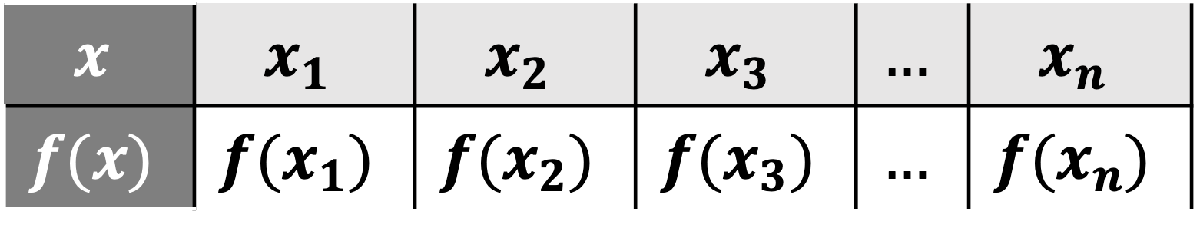

We effectively do the same thing in MATLAB, where $x$ and $f(x)$ are represented as vectors. Let's plot some functions.

Create a vector representing $\{x\,|\,x \in [-5,5]\}$ with 100 elements; call it `x``.`

Create a vector representing $f(x)=4x+5$, call it `f`.

- First, multiply each element of `x` by 4

- Next, add 5 to each element

Plot $f(x)$ using the syntax [`plot(x,f)`](https://www.mathworks.com/help/matlab/ref/plot.html?searchHighlight=plot&s_tid=srchtitle_support_results_1_plot)

Put a [title, xlabel, and ylabel](https://www.mathworks.com/help/matlab/creating_plots/add-title-axis-labels-and-legend-to-graph.html) on the figure

title('Linear Function, y(x)','Interpreter','latex')
xlabel('$x$','Interpreter','latex')
ylabel('$y(x) = 4x + 5$','Interpreter','latex')

#### **You Try It**

Create a plot of the function $g(x) = 4 \sin{(x)} - 2$ for 100 evenly-spaced values of $-\pi \leq x \leq \pi$.